# Solve System of Nonlinear Equations

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code defines and plots the implicit functions for the circle and hyperbola.

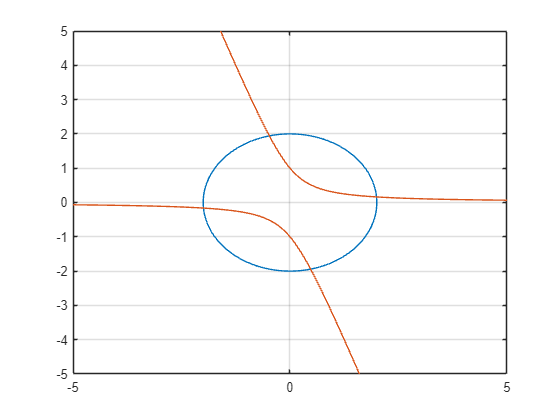

myCirc = @(x, y) x.^2 + y.^2 - 4;
myHyp = @(x, y) y.^2 + 3*x.*y - 1;
fimplicit(myCirc, [-3 3])
hold on
fimplicit(myHyp)
hold off
grid on

## Task 1

In this activity, you'll find a solution to the system of equations given by

*x^*2+*y^*2=4

*y^*2+3*x**y*=1.

The equations have been plotted for you.

rootFunction = @(w) [   myCirc(w(1),w(2)); 
                        myHyp(w(1),w(2))]

rootFunction = function_handle with value:
    @(w)[myCirc(w(1),w(2));myHyp(w(1),w(2))]


## Task 2

The curves for the two equations intersect near the point (−0.5,2). Near a point of intersection, both equations should evaluate to small numbers.

w0 = [-0.5; 2]

w0 =    -0.5000
    2.0000


z0 = rootFunction(w0)

z0 =     0.2500
         0


## Task 3

The `fsolve` function has the following syntax:

`w` `=` `fsolve``(``f``,``w0``)`

wRoot = fsolve(rootFunction, w0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


wRoot =    -0.4759
    1.9425


## Task 4

zRoot = rootFunction(wRoot)

zRoot = 1.0e-13 *

    0.8438
   -0.5596


## Task 5

For this system, `fsolve` returns a two element vector. The first element is the *x* location of the root, and the second element is the *y* location.

hold on
p = plot(wRoot(1), wRoot(2), "ro")

p =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: -0.4759
              YData: 1.9425

  Show all properties


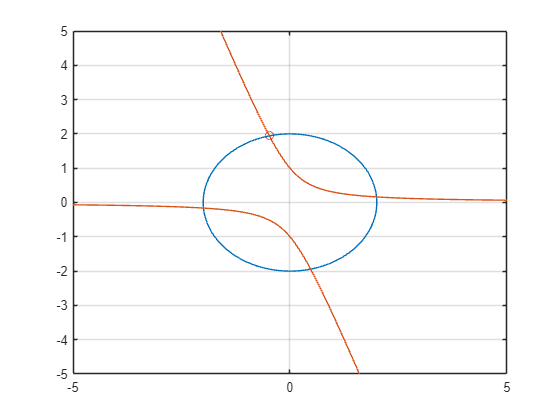

hold off